plot_type = "SWR";
save_plot = true;

input_file_path = "./LOAD.S2P";
title_str = "50 Ohm Load";
out_nickname = "load";


input_file_path = "./3DB.S2P"

out_nickname = "3db"

input_file_path = "./BANDPASS VB 2340-3530 MHZ.S2P"

out_nickname = "band_pass"


sparams  = sparameters(input_file_path);
sparams  = sparameters(sparams, 50);

if plot_type == "Smith"
    plt = smithplot(sparams);
    plt.LineWidth = 1
    plt.TitleBottom = "S-Parameters of  " + title_str;
    out_file_name = file_title + "_smith_chart.png"

end

if plot_type == "SWR"
    freqs = sparams.Frequencies;
    s11 = squeeze(sparams.Parameters(1,1,:));
    vswr_vals = vswr(s11);
    plot(freqs,vswr_vals)

    title(title_str + " Standing Wave Ratio vs. Frequency")
    out_file_name = out_nickname + "_swr.png"
end

out_file_name = "band_pass_swr.png"

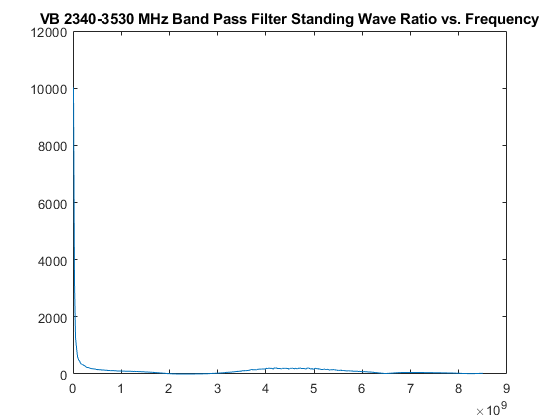


if plot_type == "ReturnLoss"
    
    plt = rfplot(sparams,1,1)
    title(title_str + " Return Loss vs. Frequency")
    out_file_name = out_nickname + "_rl.png"
end


if save_plot
    saveas(gca,"../images/" + out_file_name);
end